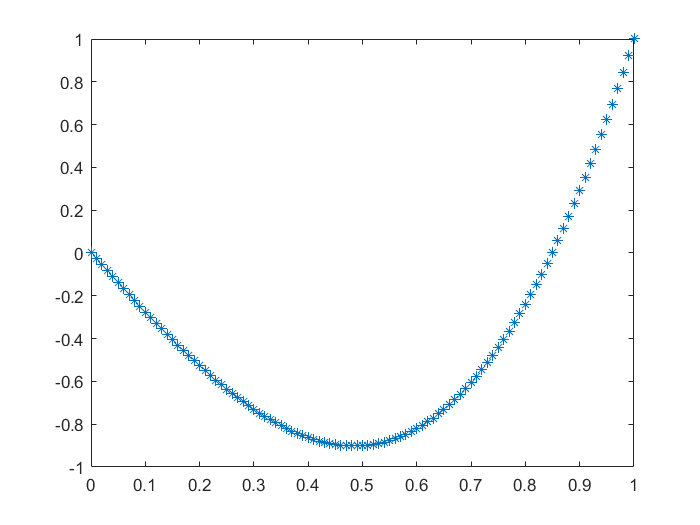

clc,clear,close all
xn = 1;x0 = 0;
n = 100;
h = (xn-x0)/n;
x = (x0+h):h:(xn-h);
A0 = [1,zeros(1,n)];
A1 = [diag(ones(1,n-1)).*(2-x.^3*h) , zeros(n-1,2)];
A2 = [zeros(n-1,1),diag(ones(1,n-1)).*(-4-6*x.^3*h^2) , zeros(n-1,1)];
A3 = [zeros(n-1,2),diag(ones(1,n-1).*(2+x.^3*h))];
A4 = [zeros(1,n),1];
A = [A0;A1+A2+A3;A4];
b = [0;12*x'.*ones(n-1,1)*h^2*4;1];
y = A\b;
plot(x0:h:xn,y,'*')